clear
load ../input/PBP2_msa_889.mat
msa = msa_w_dist.msaResult;
gapCols = msa(end, :) == '-';
msa(:, gapCols) = [];
rec_group_info = msa_w_dist.rec_name(1:length(msa_w_dist.filename)-1);

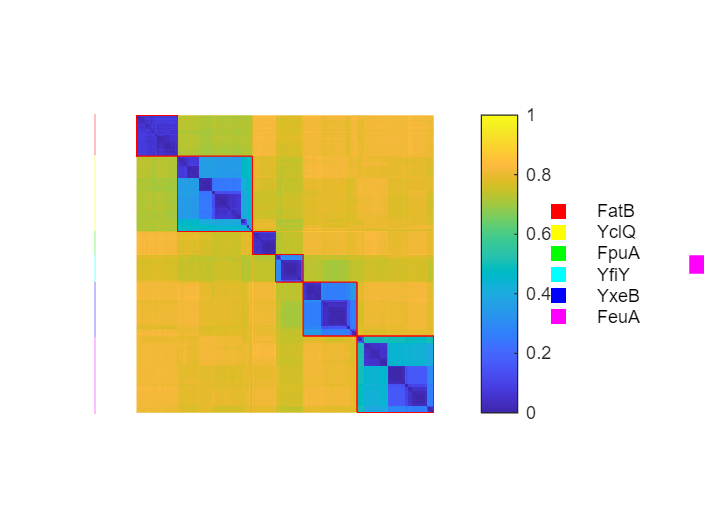

msa = msa(1:length(msa_w_dist.filename)-1,:);
distm =squareform(seqpdist(msa, 'Method', 'p-distance','PairwiseAlignment', false));
tree = linkage(distm,'average');
leafOrder = optimalleaforder(tree,distm);
dist_thresh = 0.5;
[metallore_groupid,metallore_groupnum,changedleaforder_bygroups] = Cluster_byconnection(distm,dist_thresh,leafOrder);
distm_reorder = distm(changedleaforder_bygroups,changedleaforder_bygroups);
group_info = rec_group_info (changedleaforder_bygroups);
metallore_groupid = metallore_groupid(changedleaforder_bygroups);
plot_cluster_colorbar(distm_reorder,metallore_groupid,group_info,'../Figure/6_receptors_cluster_no_ref.pdf')

group_number_info = msa_w_dist.rec_group(1:length(msa_w_dist.filename)-1);
group_number = group_number_info(changedleaforder_bygroups);
dist_vec = squareform(distm_reorder);  

if isrow(group_number)
    group_number_col = group_number';
end

s = silhouette([], group_number_col, dist_vec);
avg_silhouette = mean(s)

avg_silhouette = 0.7206

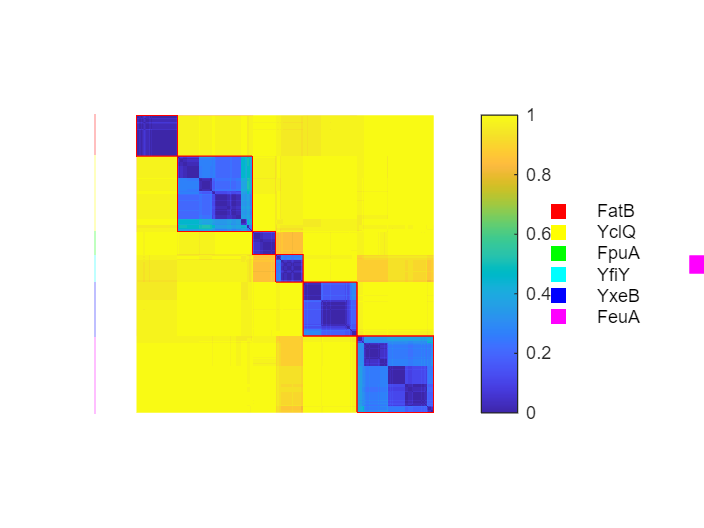

index1 = [26,43,44,45,47,52,63,64,67,68,69,70,83,84,85,105,107,110,122,126,127,130,150,180,181,185,188,192,194,196,200,210,213,217,220,222,234,240,245,272,277,284,290,294];
msa_reoreder = msa(changedleaforder_bygroups,:);
msa_test=msa_reoreder(:,index1);
distm_test = squareform(seqpdist(msa_test,'PairwiseAlignment',false,'Method','p-dist'));
plot_cluster_colorbar(distm_test,metallore_groupid,group_info,'../Figure/Feature_sites_no_ref.pdf')

dist_vec2 = squareform(distm_test);  

if isrow(group_number)
    group_number_col = group_number';
end

s = silhouette([], group_number_col, dist_vec2);
avg_silhouette = mean(s)

avg_silhouette = 0.8462

filename = msa_w_dist.filename(1:length(msa_w_dist.filename)-1);
strain_name = filename(changedleaforder_bygroups);

fasta_address = "../input/GCF_fasta_concatenated.aln"; 
sequences = fastaread(fasta_address);

ordered_sequences = cell(length(strain_name), 1);
Header = {sequences.Header};
sequences = {sequences.Sequence};

for i = 1:length(strain_name)
  
    idx = find(strcmp(Header , strain_name{i}));
    
    if ~isempty(idx)
        ordered_sequences{i} = sequences{idx(1)};
    else
        warning(['not find strain: ' strain_name{i}]);
        ordered_sequences{i} = ''; 
    end
end

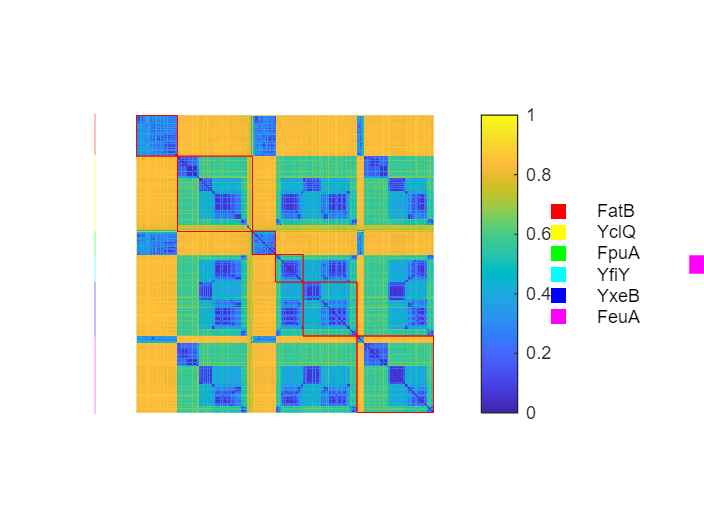

distm_phy =squareform(seqpdist(ordered_sequences, 'Method', 'p-distance','PairwiseAlignment', false));
plot_cluster_colorbar(distm_phy,metallore_groupid,group_info,'../Figure/phylogeny_no_ref.pdf')

dist_vec2 = squareform(distm_phy); 

if isrow(group_number)
    group_number_col = group_number';
end

s = silhouette([], group_number_col, dist_vec2);
avg_silhouette = mean(s)

avg_silhouette = -0.0937